# **Procesamiento de Imagenes Digitales **

# **Taller 9**

## **Image with "pepper" noise**

Lea la imagen `"pepper.tif"` . 

P = imread('pepper.tif');

Visualice la imagen en la `figura 1`. 

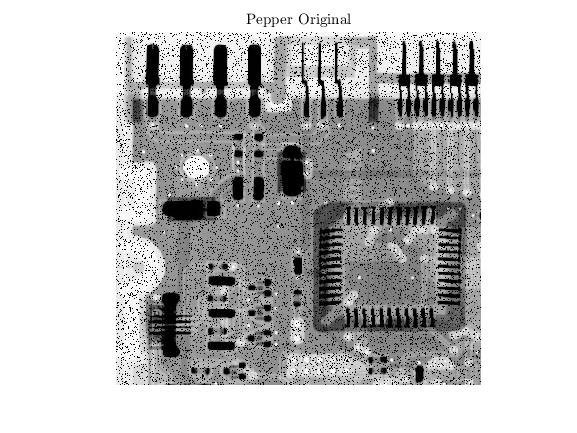

figure(1);
imshow(P);title('Pepper Original','Interpreter','Latex');

Aplique los filtros espaciales Contraharmonic mean con $Q$ positivo y negativo $(1.5, y -1.5)$ en un kernel $3 \times 3$. Visualice en un subplot horizontal y concluya. 

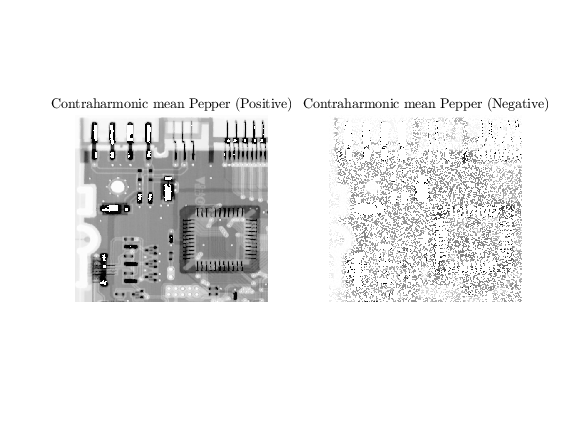

Q = 1.5;
F = imfilter(double(P).^(Q+1),ones(3,3),'replicate');
F2 = imfilter(double(P).^(-Q+1),ones(3,3),'replicate');
Fnm = imfilter(double(P).^(Q),ones(3,3),'replicate');
Fnm2 = imfilter(double(P).^(-Q),ones(3,3),'replicate');
P2 = im2uint8(mat2gray(F./Fnm));
P3 = im2uint8(mat2gray(F2./Fnm2));
figure(2);
subplot(1,2,1);imshow(P2);title('Contraharmonic mean Pepper (Positive)','Interpreter','Latex');
subplot(1,2,2);imshow(P3);title('Contraharmonic mean Pepper (Negative)','Interpreter','Latex');

Del mismo modo, aplique los filtros espaciales $min$ y $max$ en un kernel $3 \times 3$. Visualice en un subplot horizontal y concluya. 

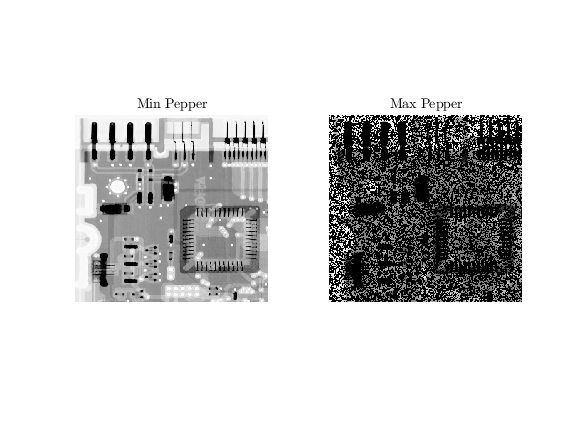

MinP = imdilate(P,ones(3,3));
MaxP = imerode(P,ones(3,3));
figure(3);
subplot(1,2,1);imshow(MinP);title('Min Pepper','Interpreter','latex');
subplot(1,2,2);imshow(MaxP);title('Max Pepper','Interpreter','Latex');

Aplique los filtros espaciales $mean$ y $median$ en un kernel $3 \times 3$. Visualice en un subplot horizontal y concluya. 

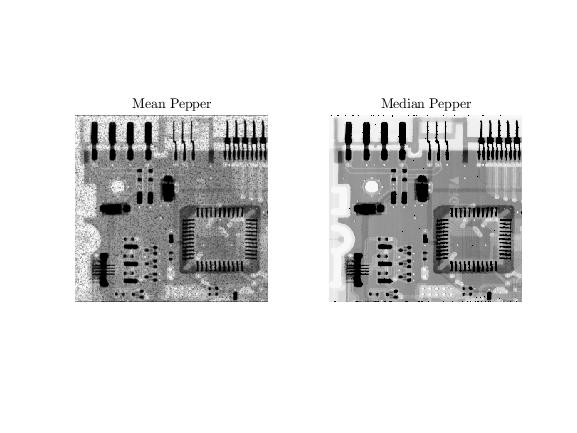

MeanP = imfilter(P,ones(3,3)/9);
MedianP = medfilt2(P,[3,3]);
figure(4);
subplot(1,2,1);imshow(MeanP);title('Mean Pepper','Interpreter','latex');
subplot(1,2,2);imshow(MedianP);title('Median Pepper','Interpreter','latex');

## **Concluciones:**

Filtro Contraharmonic mean (Positivo): Se concluye que el filtro al igual que cualquier otro filtro de media busca disminuir el ruido de la imagen, pero con la diferencia que resalta las intensidades mas altas en el caso positivo. 

Filtro Contraharmonic mean (Negativo): Por otro lado con el caso negativo del exponente la imagen disminuye las intensidades los niveles mas bajos de intensidad. Por esa razon el filtro no disminuye el ruido de la imagen si no que manda los niveles de intensidad propios de la imagen a niveles minimos.

Filtro Min: En este caso el mantener los niveles minimos de intensidad permite rellenar esos espacios de ruido de pimienta con un nivel de intensidad dentro de los niveles de intensidad de la imagene.

Filtro Max: En cambio al estar la imagen con un ruido de pimienta los maximos simpre seran los puntos negros que cubren la imagen y el filtro no mejorara la imagen.

Filtro de Media: El filtro de media no mejora la calidad de la imagen, se tiene que los filtros de media generan un efecto blur en la imagen, pero en el caso de estar la imagen con un ruido de pimienta el ruido se difumina en vez de desaparecer.

Filtro de Mediana: Por otro lado el filtro de media si cumple la funcion de desaparecer el ruido de la imagen, con una cantidad minama de ruido que no se pudo filtrar.

## **Image with "salt" noise**

Lea la imagen `"salt.tif"` . 

S = imread('salt.tif');

Visualice la imagen en la `figura 5`. 

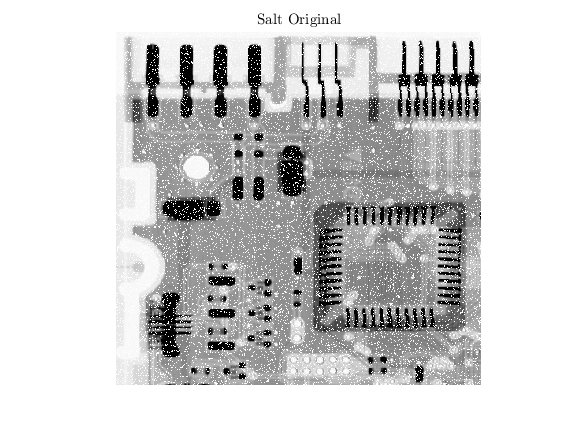

figure(5);
imshow(S);title('Salt Original','Interpreter','Latex');

Aplique los filtros espaciales Contraharmonic mean con $Q$ positivo y negativo $(1.5, y -1.5)$ en un kernel $3 \times 3$. Visualice en un subplot horizontal y concluya. 

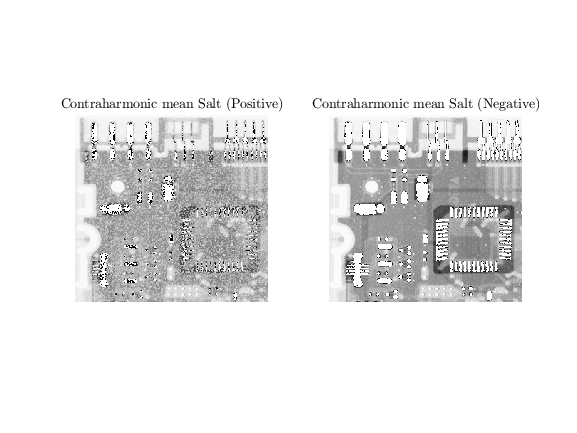

Q = 1.5;
F = imfilter(double(S).^(Q+1),ones(3,3),'replicate');
F2 = imfilter(double(S).^(-Q+1),ones(3,3),'replicate');
Fnm = imfilter(double(S).^(Q),ones(3,3),'replicate');
Fnm2 = imfilter(double(S).^(-Q),ones(3,3),'replicate');
S2 = im2uint8(mat2gray(F./Fnm));
S3 = im2uint8(mat2gray(F2./Fnm2));
figure(6);
subplot(1,2,1);imshow(S2);title('Contraharmonic mean Salt (Positive)','Interpreter','Latex');
subplot(1,2,2);imshow(S3);title('Contraharmonic mean Salt (Negative)','Interpreter','Latex');

Del mismo modo, aplique los filtros espaciales $min$ y $max$ en un kernel $3 \times 3$. Visualice en un subplot horizontal y concluya. 

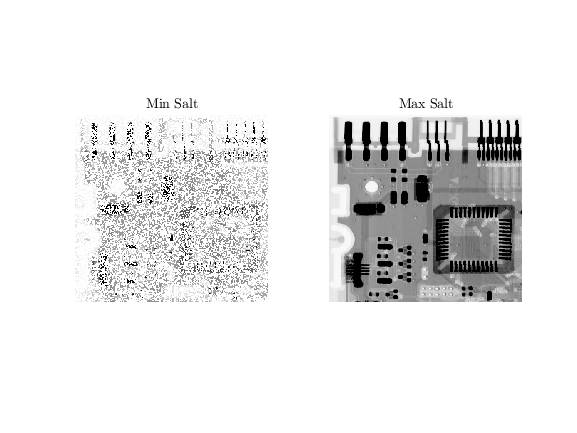

MinS = imdilate(S,ones(3,3));
MaxS = imerode(S,ones(3,3));
figure(7);
subplot(1,2,1);imshow(MinS);title('Min Salt','Interpreter','latex');
subplot(1,2,2);imshow(MaxS);title('Max Salt','Interpreter','Latex');

Aplique los filtros espaciales $mean$ y $median$ en un kernel $3 \times 3$. Visualice en un subplot horizontal y concluya. 

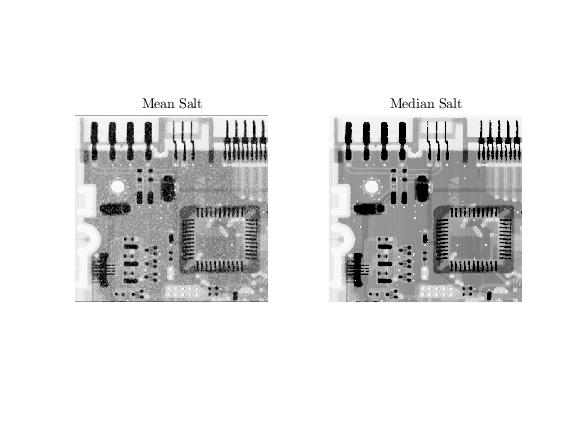

MeanS = imfilter(S,ones(3,3)/9);
MedianS = medfilt2(S,[3,3]);
figure(8);
subplot(1,2,1);imshow(MeanS);title('Mean Salt','Interpreter','latex');
subplot(1,2,2);imshow(MedianS);title('Median Salt','Interpreter','latex');

## **Conclución:**

Filtro Contraharmonic mean (Positivo): Al contener un filtro de salt el filtro positivo no puede llevar las intensidades a niveles mas altos, por lo que no se genera el filtrado del ruido de manera adecuada.

Filtro Contraharmonic mean (Negativo): En este caso sucede igual que el caso de filtrado con pimienta con la diferencia que la media en este caso mantiene un nivel de intensidad mas alto.

Filtro Min: Al filtrar los minimos y la imagen estar con ruido de sal el ruido predomina en los niveles de intensidad de la imagen.

Filtro Max: Por esta razón el filtro de maximos ayuda mas en esta situciación y el filtro mejora y disminuye el ruido.

Filtro de Media: Sucede igual que en caso anteriror.

Filtro de Mediana: Sucede igual que en el caso anteriro.

## **Image with "salt & pepper" noise**

Lea la imagen `"circuit.tif"` .

Csp = imread('circuit.tif');

Visualice la imagen en la `figura 9`. 

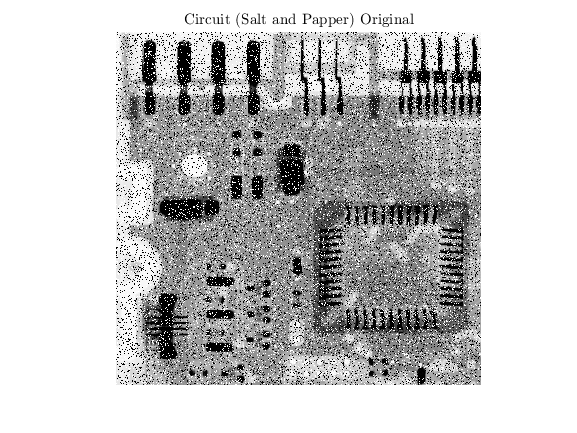

figure(9);
imshow(Csp);title('Circuit (Salt and Papper) Original','Interpreter','Latex');

Aplique los filtros espaciales Contraharmonic mean con $Q$ positivo y negativo $(1.5, y -1.5)$ en un kernel $3 \times 3$. Visualice en un subplot horizontal y concluya. 

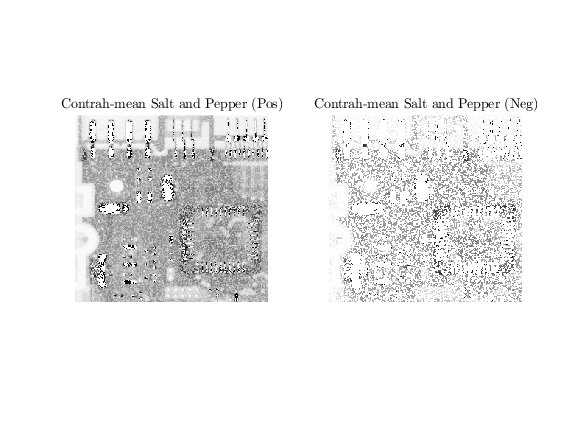

Q = 1.5;
F = imfilter(double(Csp).^(Q+1),ones(3,3),'replicate');
F2 = imfilter(double(Csp).^(-Q+1),ones(3,3),'replicate');
Fnm = imfilter(double(Csp).^(Q),ones(3,3),'replicate');
Fnm2 = imfilter(double(Csp).^(-Q),ones(3,3),'replicate');
Csp2 = im2uint8(mat2gray(F./Fnm));
Csp3 = im2uint8(mat2gray(F2./Fnm2));
figure(10);
subplot(1,2,1);imshow(Csp2);title('Contrah-mean Salt and Pepper (Pos)','Interpreter','Latex');
subplot(1,2,2);imshow(Csp3);title('Contrah-mean Salt and Pepper (Neg)','Interpreter','Latex');

Del mismo modo, aplique los filtros espaciales $min$ y $max$ en un kernel $3 \times 3$. Visualice en un subplot horizontal y concluya. 

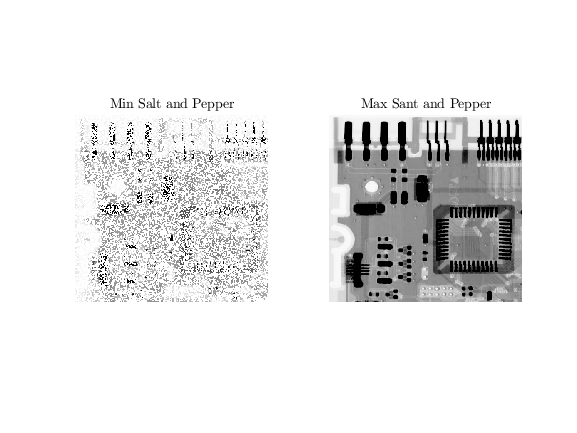

MinCsp = imdilate(S,ones(3,3));
MaxCsp = imerode(S,ones(3,3));
figure(11);
subplot(1,2,1);imshow(MinCsp);title('Min Salt and Pepper','Interpreter','latex');
subplot(1,2,2);imshow(MaxCsp);title('Max Sant and Pepper','Interpreter','Latex');

Aplique los filtros espaciales $mean$ y $median$ en un kernel $3 \times 3$. Visualice en un subplot horizontal y concluya. 

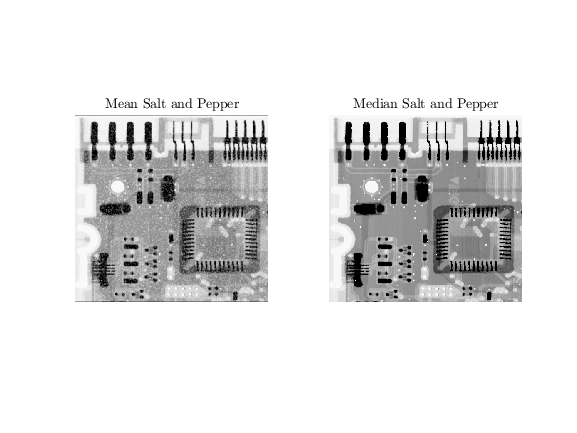

MeanCsp = imfilter(S,ones(3,3)/9);
MedianCsp = medfilt2(S,[3,3]);
figure(12);
subplot(1,2,1);imshow(MeanCsp);title('Mean Salt and Pepper','Interpreter','latex');
subplot(1,2,2);imshow(MedianCsp);title('Median Salt and Pepper','Interpreter','latex');

## **Concliciones:**

Filtro Contraharmonic mean (Positivo): El filtro busca llevar los niveles de intensidad mas altos pero no llega a mejorar por estar con un ruido de sal y pimienta.

Filtro Contraharmonic mean (Negativo): El filtro busca llevar los niveles de intensidad mas bajos pero no llega a mejorar por estar con un ruido de sal y pimienta.

Filtro Min: En esta imagen los niveles de ruido de sal son mas altos y por lo tanto la imegen emperora al filtrar por los minimos.

Filtro Max: Al estar los niveles de ruido de sal mas altos la imagen mejora manteniendo los maximos.

Filtro de Media: Al igual que las otros caso el filtro difumina el ruido.

Filtro de Mediana: El filtro de mediana se podría decir que es por excelencia el recomendado para filtrar el ruido de sal o pimiento o ambos a la vez.